clear; clc;
close all;

%% Text Size
set(0,'DefaultAxesFontsize',6);
set(0,'DefaultTextFontsize',6);

%% Text Fonts
set(0,'DefaultTextFontname','Arial');
set(0,'DefaultAxesFontname','Arial');

figsize = [10 15 8 4];
figpos = [0.12 0.2 0.75 0.7];
lw = 0.8;
scattersize = 100;

% allcoeff = zeros(8*6, 4);
% line = 1;
% Nrlist = [10 20 30 50 100 200 300 500];
% SRlist = [0.5 0.8 1.1 1.4 1.7 2];
% for i = 1:8
%     Nr = Nrlist(i);
% for j = 1:6
%     SR = SRlist(j);
%     stm = 0;
%     pc = 0;
% for k = 1:5
%     filename = ['esnseed/esn_Nr' num2str(Nr) 'SR' num2str(SR*10) 'No' num2str(k)];
%     load(filename, 'stm_allcoeff', 'pc_allcoeff');
%     stm = stm + stm_allcoeff;
%     pc = pc + pc_allcoeff;
% end
%     stm = stm/5;
%     pc = pc/5;
%     allcoeff(line, 1) = i;
%     allcoeff(line, 2) = j;
%     allcoeff(line, 3) = stm;
%     allcoeff(line, 4) = pc;
%     line = line + 1;
% end
% end
% 
% save('data/capabilitydata', "Nrlist", "SRlist", "allcoeff");

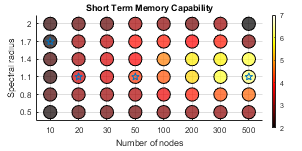

load('data/fig5_capabilitydata');

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',figsize);
set(gca,'Position', figpos);
set(gcf,'Visible','on');

scatter(allcoeff(:,1), allcoeff(:,2), scattersize*ones(8*6,1), allcoeff(:,3), 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceAlpha',.7);
hold on;
plot(1,5,'pentagram', Color= [0 0.4470 0.7410]);
hold on;
plot(2,3,'pentagram', Color= [0 0.4470 0.7410]);
hold on;
plot(4,3,'pentagram', Color= [0 0.4470 0.7410]);
hold on;
plot(8,3,'pentagram', Color= [0 0.4470 0.7410]);

grid on;
title('Short Term Memory Capability');
xlabel('Number of nodes');
ylabel('Spectral radius');
xticks(1:8);
yticks(1:6);
xticklabels({num2str(Nrlist(1)), num2str(Nrlist(2)), num2str(Nrlist(3)), num2str(Nrlist(4)), ...
    num2str(Nrlist(5)), num2str(Nrlist(6)), num2str(Nrlist(7)), num2str(Nrlist(8))});
yticklabels({num2str(SRlist(1)), num2str(SRlist(2)), num2str(SRlist(3)), ...
    num2str(SRlist(4)), num2str(SRlist(5)), num2str(SRlist(6))});
xlim([0.5 8.5]);
ylim([0.5 6.5]);
colormap("hot");
cb = colorbar();
cb.Position = [0.9, 0.15, 0.015, 0.75];
clim([2, 7]);

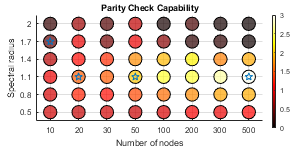


figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',figsize);
set(gca,'Position', figpos);
set(gcf,'Visible','on');

scatter(allcoeff(:,1), allcoeff(:,2), scattersize*ones(8*6,1), allcoeff(:,4), 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceAlpha',.7);
hold on;
plot(1,5,'pentagram', Color= [0 0.4470 0.7410]);
hold on;
plot(2,3,'pentagram', Color= [0 0.4470 0.7410]);
hold on;
plot(4,3,'pentagram', Color= [0 0.4470 0.7410]);
hold on;
plot(8,3,'pentagram', Color= [0 0.4470 0.7410]);

grid on;
title('Parity Check Capability');
xlabel('Number of nodes');
ylabel('Spectral radius');
xticks(1:8);
yticks(1:6);
xticklabels({num2str(Nrlist(1)), num2str(Nrlist(2)), num2str(Nrlist(3)), num2str(Nrlist(4)), ...
    num2str(Nrlist(5)), num2str(Nrlist(6)), num2str(Nrlist(7)), num2str(Nrlist(8))});
yticklabels({num2str(SRlist(1)), num2str(SRlist(2)), num2str(SRlist(3)), ...
    num2str(SRlist(4)), num2str(SRlist(5)), num2str(SRlist(6))});
xlim([0.5 8.5]);
ylim([0.5 6.5]);
colormap("hot");
cb = colorbar();
cb.Position = [0.9, 0.15, 0.015, 0.75];
clim([0, 3]);


% leg = legend([p{1} p{2} p{3} p{4} p{5} p{6}], {'S_1','S_2','S_3','S_4','S_5','S_6'},'Location','southeast');
% legend('boxoff');
% leg.ItemTokenSize = [10 10];